# Optimization of Ramjet Engine

## Problem Formulation


$$\min_x \;\;\textrm{TSFC}$$
 

where $x\;=\;\left\lbrack \begin{array}{c}
\textrm{alt}\\
\eta_d \\
\eta_n \\
A_e \\
M_1 \\
M_2 \\
T_{\textrm{t3},\max } \\
q_f 
\end{array}\right\rbrack$

Subject to:

[TSFC] = f(x) (given by the design tool)

   
$$\begin{array}{l}
\mathrm{alt}-4000\ge 0\\
{\;M}_{1\;} -2\ldotp 4\ge 0\\
M_2 -0\ldotp 1\ge 0\\
\mathrm{TSFC}\ge 0\\
5000-\mathrm{Thrust}\le 0\\
\\
{2400-\;T}_{\mathrm{t3},\max } =0\\
\eta_d -\left(\ldotp 95-0\ldotp 0125{*M}_1 \right)=0\\
\eta_n -\ldotp 94=0\\
q_{f\;} -42\ldotp 3*{10}^6 =0\\
A_e -0\ldotp 015=0
\end{array}$$


    where w1 and w2 are arbitrary weights picked by the designer


$$w=\left(1,0\ldotp 001\right)$$


w = [1;0.001];
x0 = [10000; .92; .94; .015; 3; .15; 2400; 42.3*10^6];

fun = @(x)objectiveFunction(x);
nonlcon = @Contraints;
options = optimoptions('fmincon','MaxFunctionEvaluations',20000, 'MaxIterations',100, 'PlotFcn','optimplotfval','CheckGradients',true, 'Display','iter-detailed')

options =   fmincon options:

   Options used by current Algorithm ('interior-point'):
   (Other available algorithms: 'active-set', 'sqp', 'sqp-legacy', 'trust-region-reflective')

   Set properties:
               CheckGradients: 1
                      Display: 'iter-detailed'
       MaxFunctionEvaluations: 20000
                MaxIterations: 100
                      PlotFcn: 'optimplotfval'

   Default properties:
                    Algorithm: 'interior-point'
           BarrierParamUpdate: 'monotone'
          ConstraintTolerance: 1.0000e-06
        EnableFeasibilityMode: 0
     FiniteDifferenceStepSize: 'sqrt(eps)'
         FiniteDifferenceType: 'forward'
         HessianApproximation: 'bfgs'
                   HessianFcn: []
           HessianMultiplyFcn: []
                  HonorBounds: 1
          

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       9    2.643657e-01    2.644e-01    5.921e-02
    1      19    2.630967e-01    2.631e-01    8.249e-02    2.653e-02
    2      29    2.595778e-01    2.596e-01    1.758e-01    5.756e-02
    3      39    2.563068e-01    2.563e-01    3.058e-01    4.785e-02
    4      48    2.413795e-01    2.414e-01    7.126e-01    1.344e-01
    5      57    2.153339e-01    2.153e-01    3.968e-01    1.642e-01
    6      66    2.097575e-01    2.098e-01    6.101e-01    3.977e-02
    7      75    2.094637e-01    2.095e-01    6.210e-01    2.076e-02
    8      86    2.094397e-01    2.094e-01    6.210e-01    2.407e+00
    9      95    1.944367e-01    1.944e-01    6.195e-01    1.728e+03
   10     104    1.943552e-01    1.944e-01    6.195e-01    9.558e+00
   11     114    1.907915e-01    1.908e-01    6.123e-01    1.071e+03
   12     123    1.906671e-01    1.907e-01    6

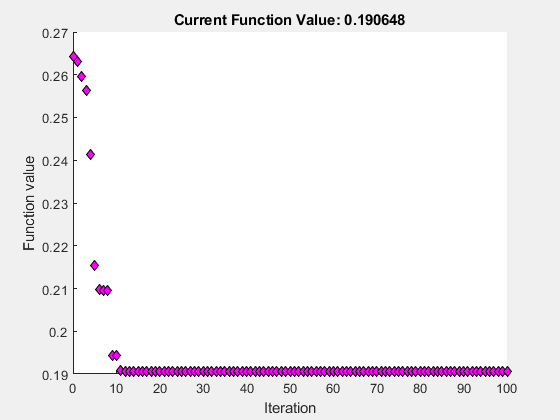


Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 1.000000e+02.



x = fmincon(fun, x0, [],[],[],[],[],[],nonlcon,options);




% after optimization
[~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~,Thrust, ~, TSFC, ~, ~, ~] = RamjetCalculator(x(1), x(2), x(3), x(4), x(5), x(6), x(7), x(8))

Thrust = 5.0000e+03

TSFC = 0.1906


table(x(1), x(2), x(3), x(4), x(5), x(6), x(7), x(8), 'VariableNames',{'Flight Altitude','Diffuser Eff.', 'Nozzle Eff.', 'A_e','M1', 'M2','Tt3_max', 'q_f' })

ans = 1×8 table
    Flight Altitude    Diffuser Eff.    Nozzle Eff.     A_e     M1       M2       Tt3_max      q_f   
    _______________    _____________    ___________    _____    ___    _______    _______    ________

        7090.9            0.92384          0.94        0.015    2.4    0.32789     2400      4.23e+07


function f = objectiveFunction(x)
    [~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~,~, ~, TSFC, ~, ~, ~] = RamjetCalculator(x(1), x(2), x(3), x(4), x(5), x(6), x(7), x(8));
    f = TSFC;
end

function [ineq_cons, eq_cons] = Contraints(x)

[~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~,Thrust, ~, TSFC, ~, ~, ~] = RamjetCalculator(x(1), x(2), x(3), x(4), x(5), x(6), x(7), x(8));

    eq_cons = [x(2)-(0.95-0.0125*x(5));
               x(3)-0.94;
               x(8)-42.3*10^6;
               x(7)-2400;
               x(4)-0.015];

    ineq_cons = [4000-x(1);
                2.4-x(5);
                0.1-x(6);
                TSFC;
                5000-Thrust];
end